# Beam reconstruction

Main file to reconstruct the beam.

Date: 09/09/2021

E. Felcini

% Read example files from extraction simulations 
% For Septum

fileName = 'tracksumm_setti.txt';
Comments_String = {'@ NAME  ',  'cnao3ese$end'};

nHeader = 0;
readFormat = '%f %f %f %f %f %f %f %f %f %s %s';

Input = 'AsIs_TwissUpdate';

folder = ['.\Input_Particles\CNAO_TM_strengths - R1 - ', Input,'\'];
[pID1,turn1,x1,px1,y1,py1,t1,pt1,s1] = Read_Particles_Setti([folder,fileName], readFormat, nHeader ,Comments_String);

folder = ['.\Input_Particles\CNAO_TM_strengths - R2 - ', Input,'\'];
[pID2,turn2,x2,px2,y2,py2,t2,pt2,s2] = Read_Particles_Setti([folder,fileName], readFormat, nHeader ,Comments_String);

folder = ['.\Input_Particles\CNAO_TM_strengths - R3 - ', Input,'\'];
[pID3,turn3,x3,px3,y3,py3,t3,pt3,s3] = Read_Particles_Setti([folder,fileName], readFormat, nHeader ,Comments_String);

%Join the vectors
pt = [pt1;pt2;pt3];
x = [x1;x2;x3]; px = [px1;px2;px3];
y = [y1;y2;y3]; py = [py1;py2;py3];


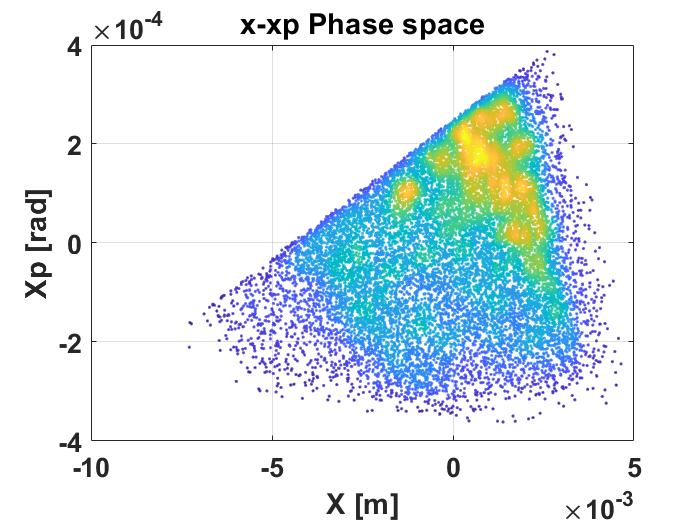


% Set dispersion function and its derivative
D = 0; Dp = 0;    

x = x + D*pt;
x = x - mean(x);

px = px + Dp*pt;
px = px - mean(px);

y = y - mean(y);
py = py - mean(py);

figure; hold on;
scatplot(x,px);
xlabel('X [m]'); ylabel('Xp [rad]'); title('x-xp Phase space');

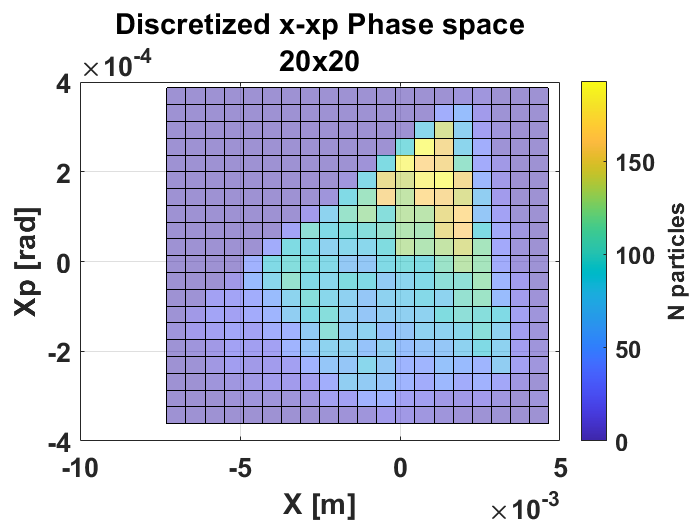


%% Subdivision of the phase space with a grid
n_x_grid = 21;
n_px_grid = 21;

x_lin = linspace(min(x), max(x), n_x_grid);
px_lin = linspace(min(px), max(px), n_px_grid);

[X_grid,PX_grid] = meshgrid(x_lin,px_lin);
X_PX_grid = cell(size(X_grid));
count_grid = zeros(size(X_grid));

% figure; hold on;
% surf(X_grid,PX_grid,count_grid,'FaceAlpha',0.2);
% xlabel('X [m]'); ylabel('Xp [rad]');
for i=1:n_x_grid-1
    for j=1:n_px_grid-1
        if i<n_x_grid-1;   id_x = find((x>=x_lin(i) & x<x_lin(i+1)));
        else;  id_x = find((x>=x_lin(i) & x<=x_lin(i+1))); end
        if j<n_px_grid-1; id_px = find(px>=px_lin(j) & px<px_lin(j+1));
        else; id_px = find(px>=px_lin(j) & px<=px_lin(j+1)); end
        [val,~]=intersect(id_x,id_px);
        X_PX_grid{j,i} = [x(val), px(val)];
        count_grid(j,i) = size(X_PX_grid{j,i},1);
    end
end
    
figure; hold on;
surf(X_grid,PX_grid,count_grid,'FaceAlpha',0.5);
xlabel('X [m]'); ylabel('Xp [rad]'); title(["Discretized x-xp Phase space",strcat(string(n_x_grid-1),'x',string(n_px_grid-1))]);  
c = colorbar('EastOutside'); c.Label.String = 'N particles'; c.Label.FontSize = 14;

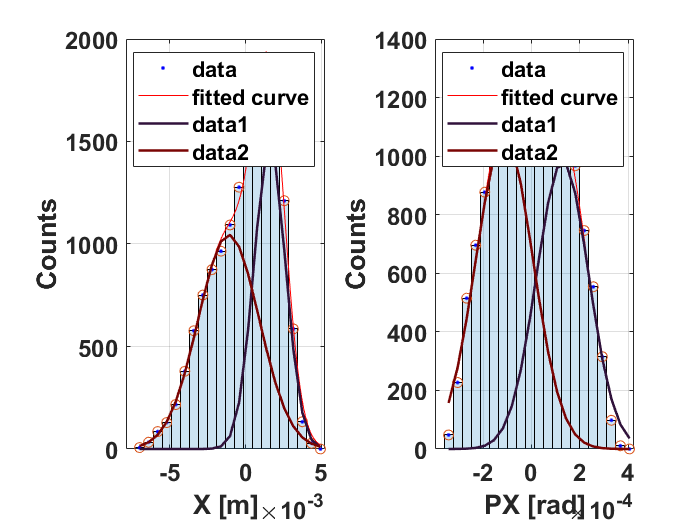


% Representation of beam distribution with n_fun Gaussian functions

n_fun = 2; %number of functions to be used in the fit

f_gauss = @(Z,x) Z(1)*exp(-((x-Z(2))/Z(3)).^2);

x_bin = (x_lin+(x_lin(2)-x_lin(1))/2).';
count_bin_x = sum(count_grid,1)';

px_bin = (px_lin+(px_lin(2)-px_lin(1))/2).';
count_bin_px = sum(count_grid,2);


figure; 

% Analysis for X
subplot(1,2,1);
hold on;

histogram(x,'BinEdge',x_lin,'FaceAlpha',0.2);
plot(x_bin,count_bin_x,'o');

f1 = fit(x_bin,count_bin_x,['gauss',num2str(n_fun)]);
A = reshape(coeffvalues(f1),[],n_fun); %save the coefficients in a matrix

plot(f1,x_bin,count_bin_x);

CM = turbo(n_fun);
for i=1:n_fun
    plot(x_bin,f_gauss(A(:,i)',x_bin),'-', 'LineWidth',1.5, "Color",CM(i,:));
end

xlabel('X [m]'); ylabel('Counts');


% Analysis for PX
subplot(1,2,2);
hold on;

histogram(px,'BinEdge',px_lin,'FaceAlpha',0.2);
plot(px_bin,count_bin_px,'o');


f2 = fit(px_bin,count_bin_px,['gauss',num2str(n_fun)]);
B = reshape(coeffvalues(f2),[],n_fun); %save the coefficients in a matrix

plot(f2,px_bin,count_bin_px);
for i=1:n_fun
    plot(px_bin,f_gauss(B(:,i)',px_bin),'-', 'LineWidth',1.5, "Color",CM(i,:));
end

xlabel('PX [rad]'); ylabel('Counts');

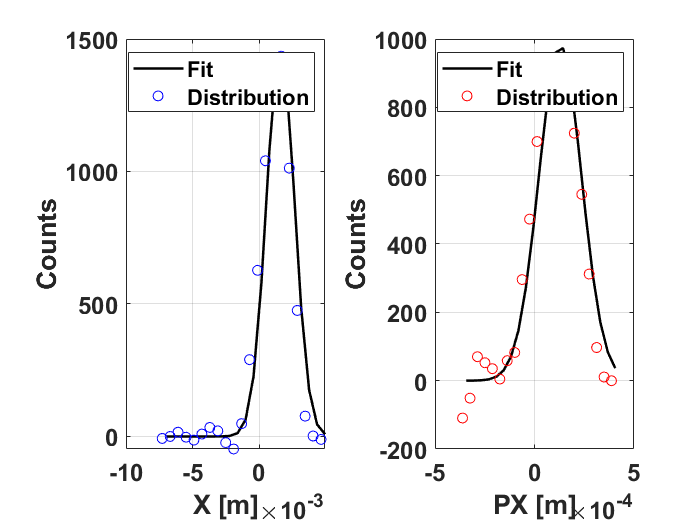

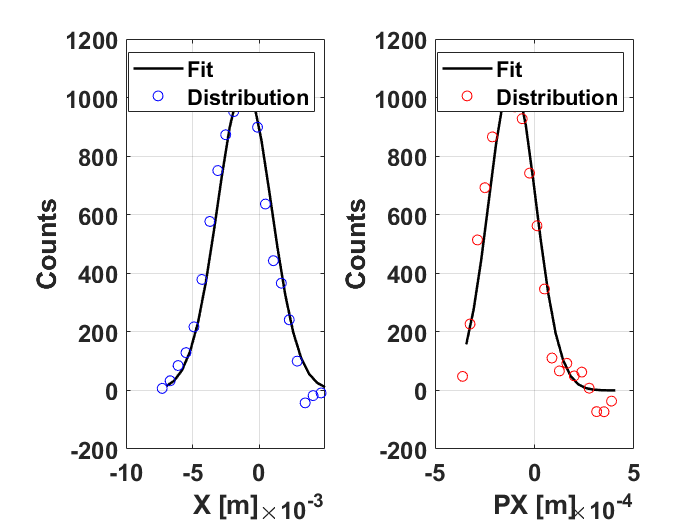

% Decompose the the beam in n_fun distributions

count_bin_x_f = cell(1,n_fun);
count_bin_px_f = cell(1,n_fun);
for i=1:n_fun
    count_bin_x_f{i} = count_bin_x;
    count_bin_px_f{i} = count_bin_px;
    figure; title(['Distribution n',num2str(i)])
    subplot(1,2,1); hold on;
    xlabel('X [m]'); ylabel('Counts'); 
    
    subplot(1,2,2); hold on;
    xlabel('PX [m]'); ylabel('Counts');     
    
    subplot(1,2,1);
    plot(x_bin,f_gauss(A(:,i)',x_bin),'-k', 'LineWidth',1.5);
    
    subplot(1,2,2);
    plot(px_bin,f_gauss(B(:,i)',px_bin),'-k', 'LineWidth',1.5);    
    
    for j=1:n_fun
        if j~=i
            count_bin_x_f{i} = count_bin_x_f{i} - f_gauss(A(:,j)',x_bin);  
            count_bin_px_f{i} = count_bin_px_f{i} - f_gauss(B(:,j)',px_bin); 
        end
    end
    subplot(1,2,1);
    plot(x_lin,count_bin_x_f{i},'bo');
    legend('Fit','Distribution');
    subplot(1,2,2);
    plot(px_lin,count_bin_px_f{i},'ro');
    legend('Fit','Distribution');
end